# MLP Model of SI Engine Torque Dynamics

This example describes modeling the nonlinear torque dynamics of a spark-ignition (SI) engine as a Multi-Layer Perceptron model. The identified model can be used for hardware-in-the-loop (HIL) testing, powertrain control, diagnostic, and training algorithm design. For example, you can use the model for aftertreatment control and diagnostics algorithm development. For more information on nonlinear MLP model, see [MLP](https://www.mathworks.com/help/releases/R2024b/ident/ref/idneuralstatespace.createmlpnetwork.html?searchHighlight=MLP&s_tid=doc_srchtitle)

You use measurements of the system inputs and outputs to identify the model. This data can come from measurements on a real engine or a high-fidelity model such as one created using the Powertrain Blockset™ SI Reference application. 

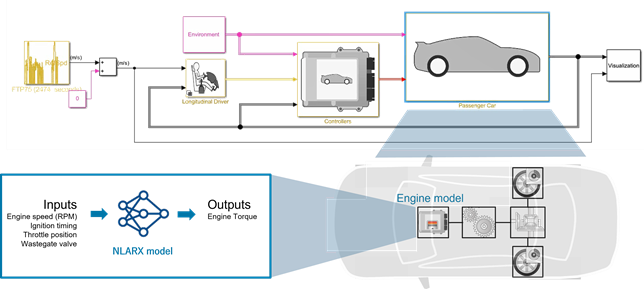

## Data Preparation

Load and display the engine data timetable.

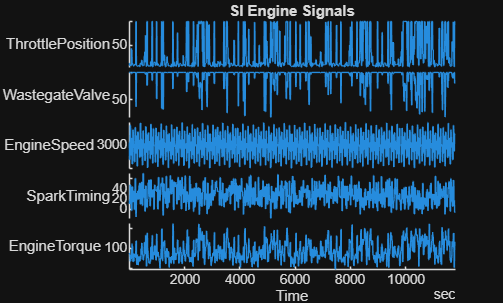

load SIEngineData IOData
stackedplot(IOData)
title('SI Engine Signals')

  The timetable contains over one hundred thousands observations of five variables measured at 10 Hz.

- Throttle position (degrees)

- Wastegate valve area (aperture percentage) 

- Engine speed (RPM)

- Spark timing (degrees)

- Engine torque (N m)

Split the data into estimation (first 60000 data points) and validation (remaining data points) portions.

eData = IOData(1:6e4,:);     % portion used for estimation
%change it to 8e4
vData = IOData(6e4+1:end,:); % portion used for validation

Downsample the training data by a factor of 10. This helps speed up the model training process and also limits the focus of the fit to a lower frequency region. 

% Remove this portion ple datasets 10 times
eDataD = idresamp(eData,[1 10]); 
vDataD = idresamp(vData,[1 10]);
eDataD.Properties.TimeStep;


Add inputs and outputs

Inputs = ["ThrottlePosition","WastegateValve","EngineSpeed","SparkTiming"];
Output = "EngineTorque";

Start Reduced Order Modeling App and Select from Imported data and Choose IOData as input. Setup Engine Torque as output

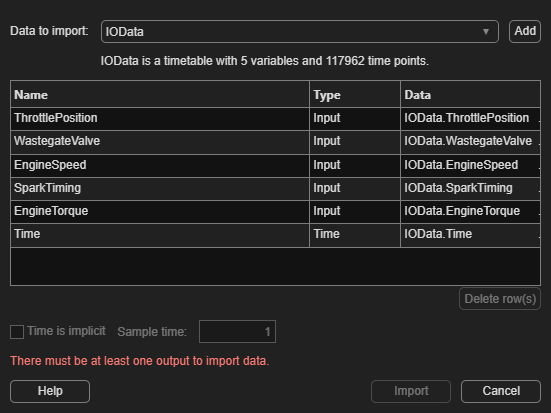

useROMApp=true;
if(useROMApp)
    reducedOrderModeler;% Add screen shot of import Data
 

Please select MATLAB Variable

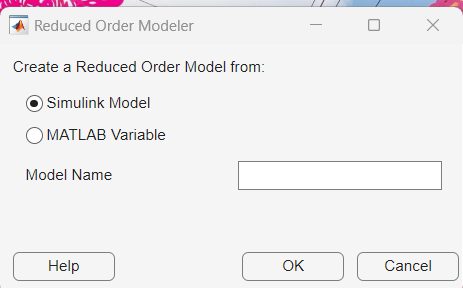

Once selected please select MATLAB variable we want to import in our case it is IOData

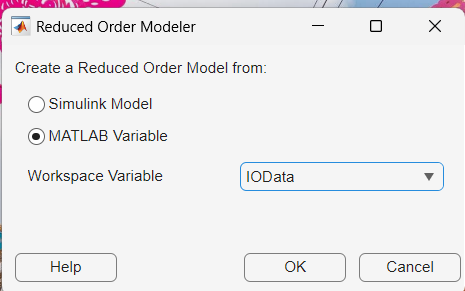

Once Data is selected please select required inputs and outputs, Engine Torque is what we want  to predict using ROM

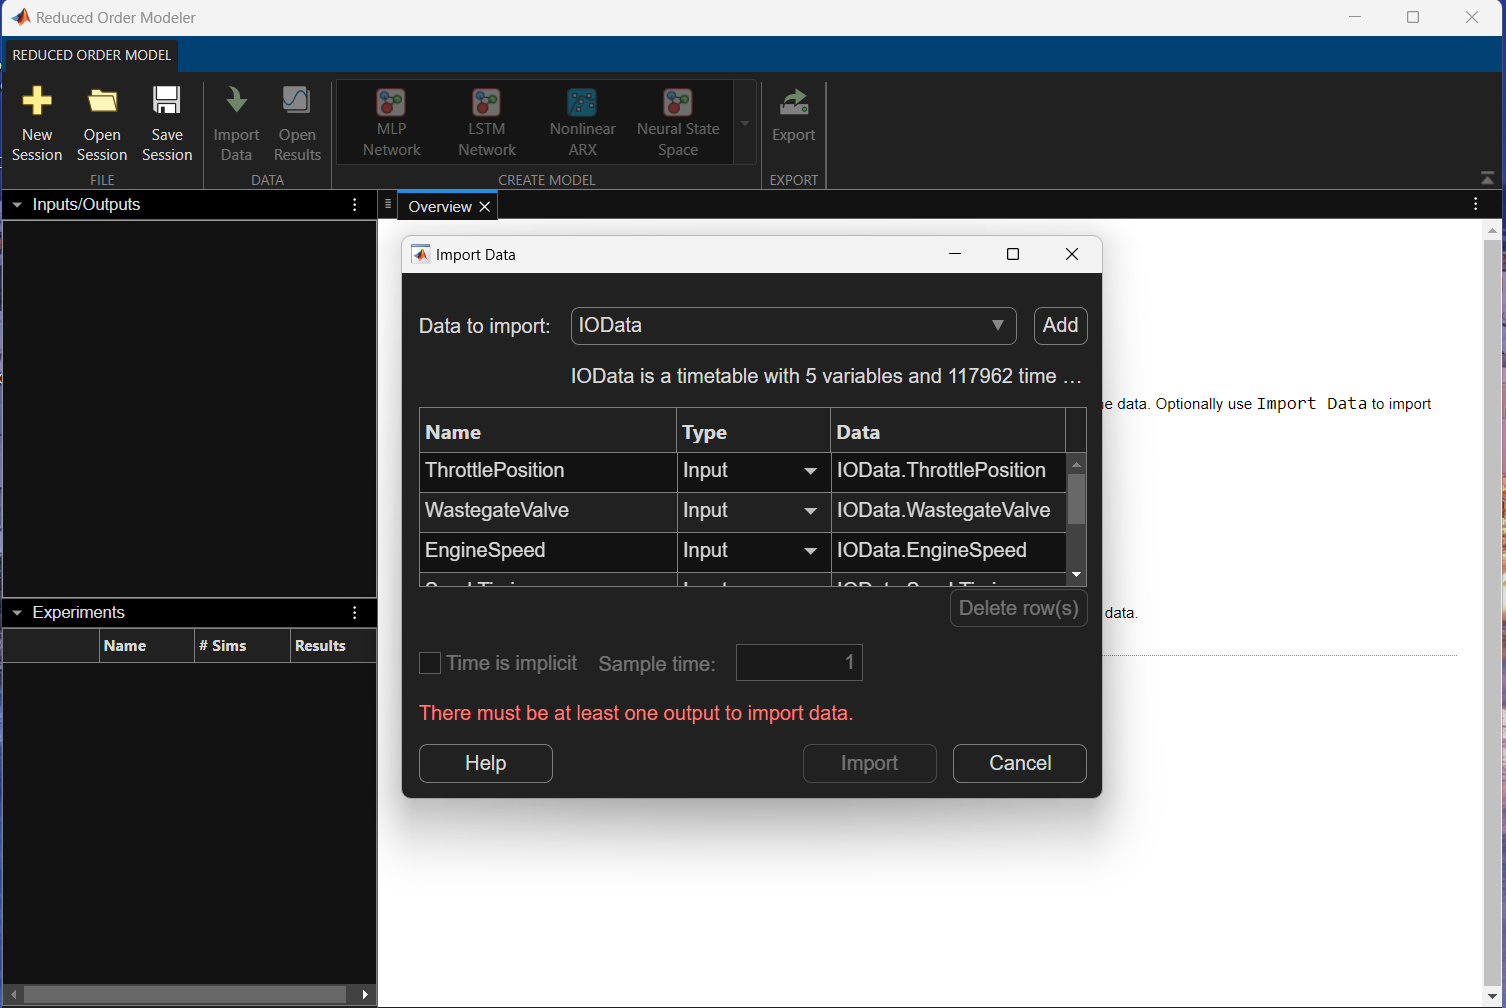

Examine the Randomness of Inputs and Outputs if we see strong correlation please select one of the correlated inputs and do the same for outputs.

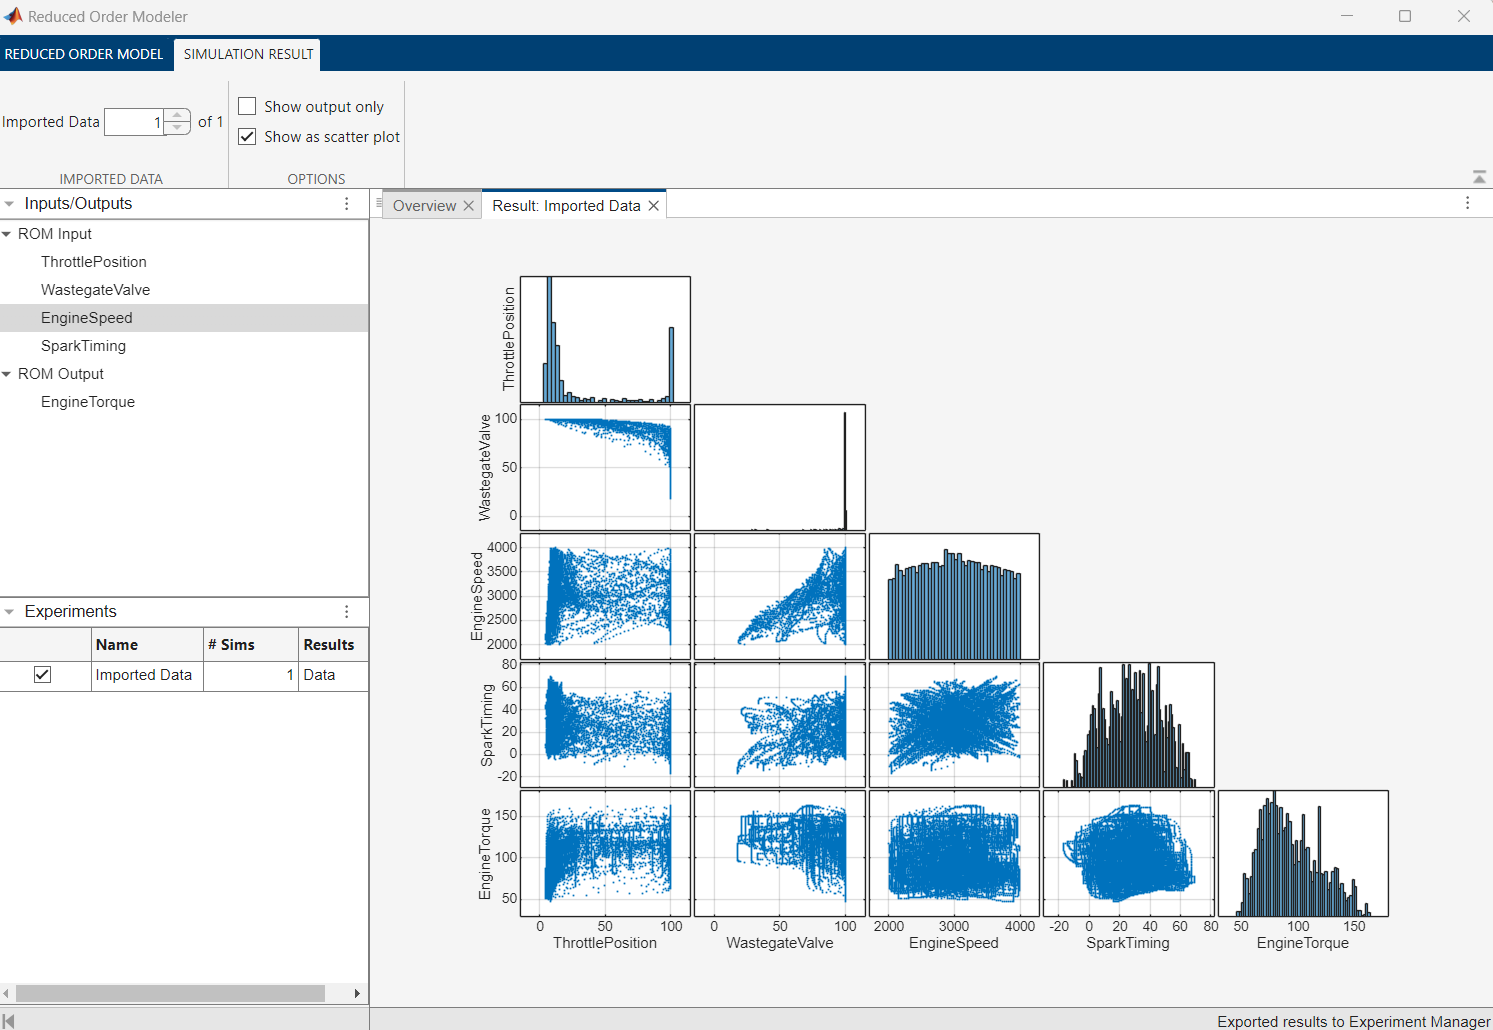

Now set up an experiment that uses MLP with following parameters

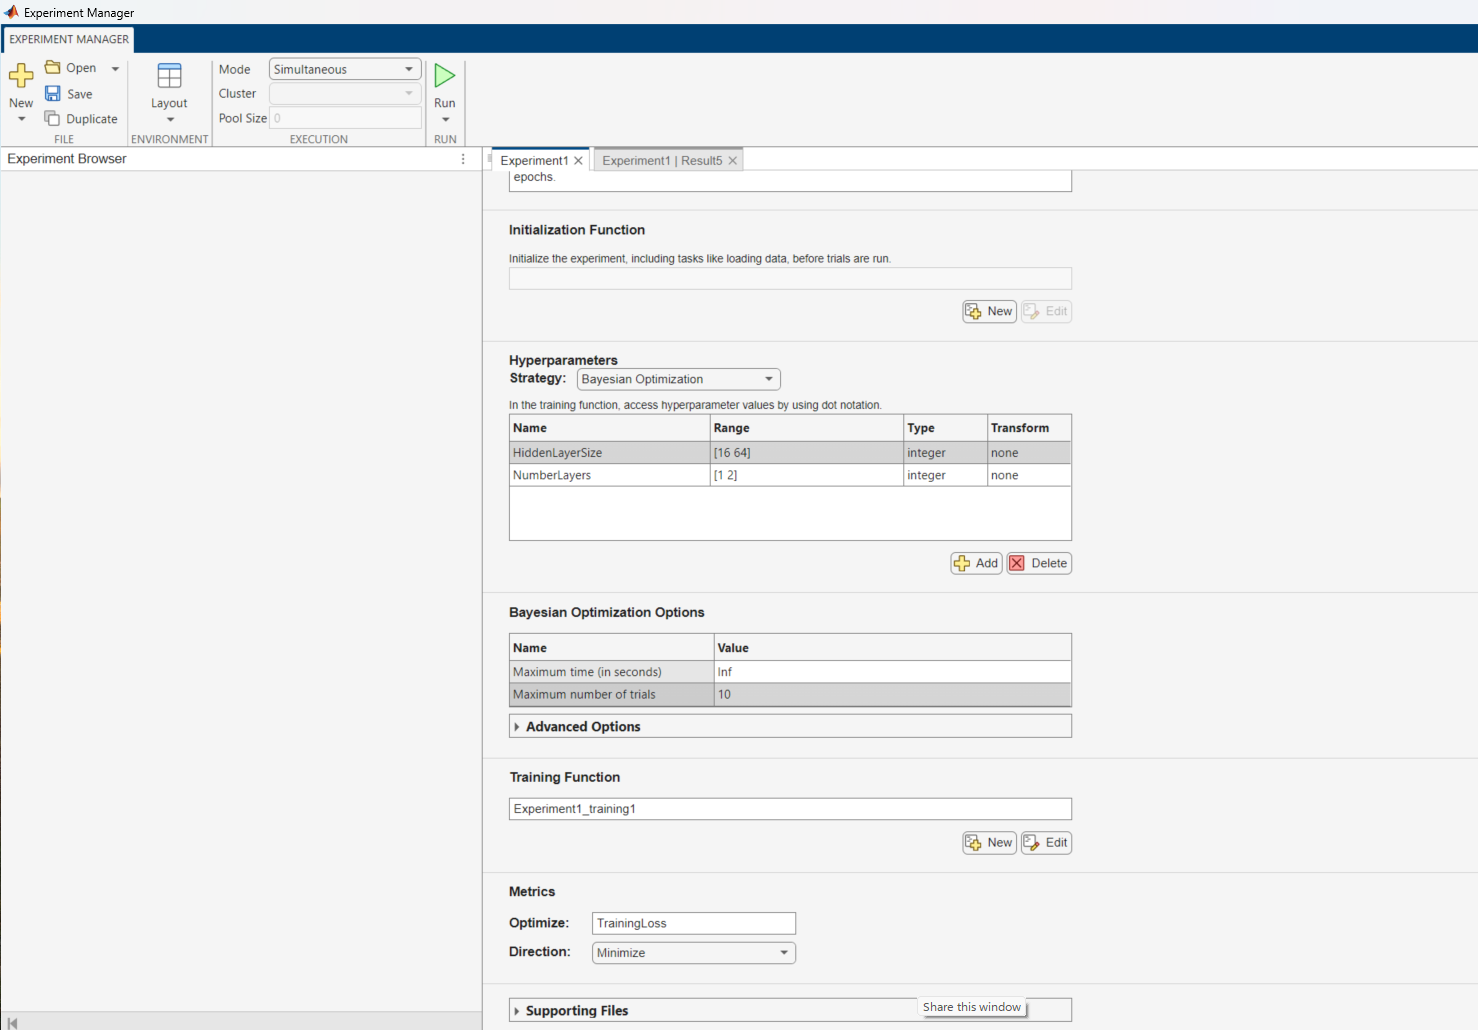

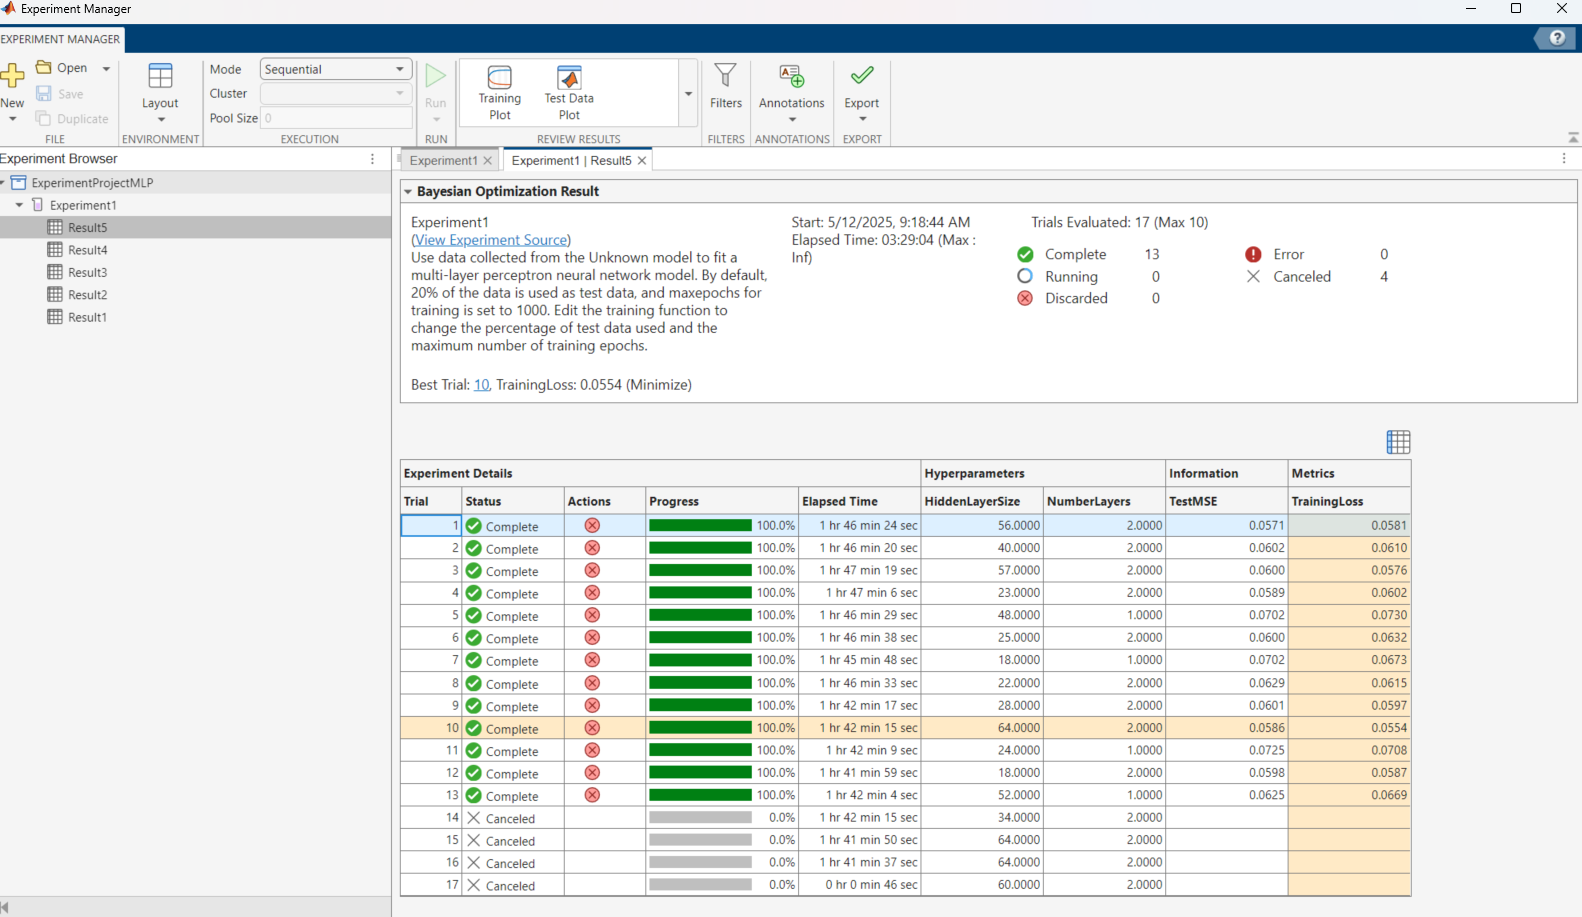

Pick the Best Model and export trainingOutput.

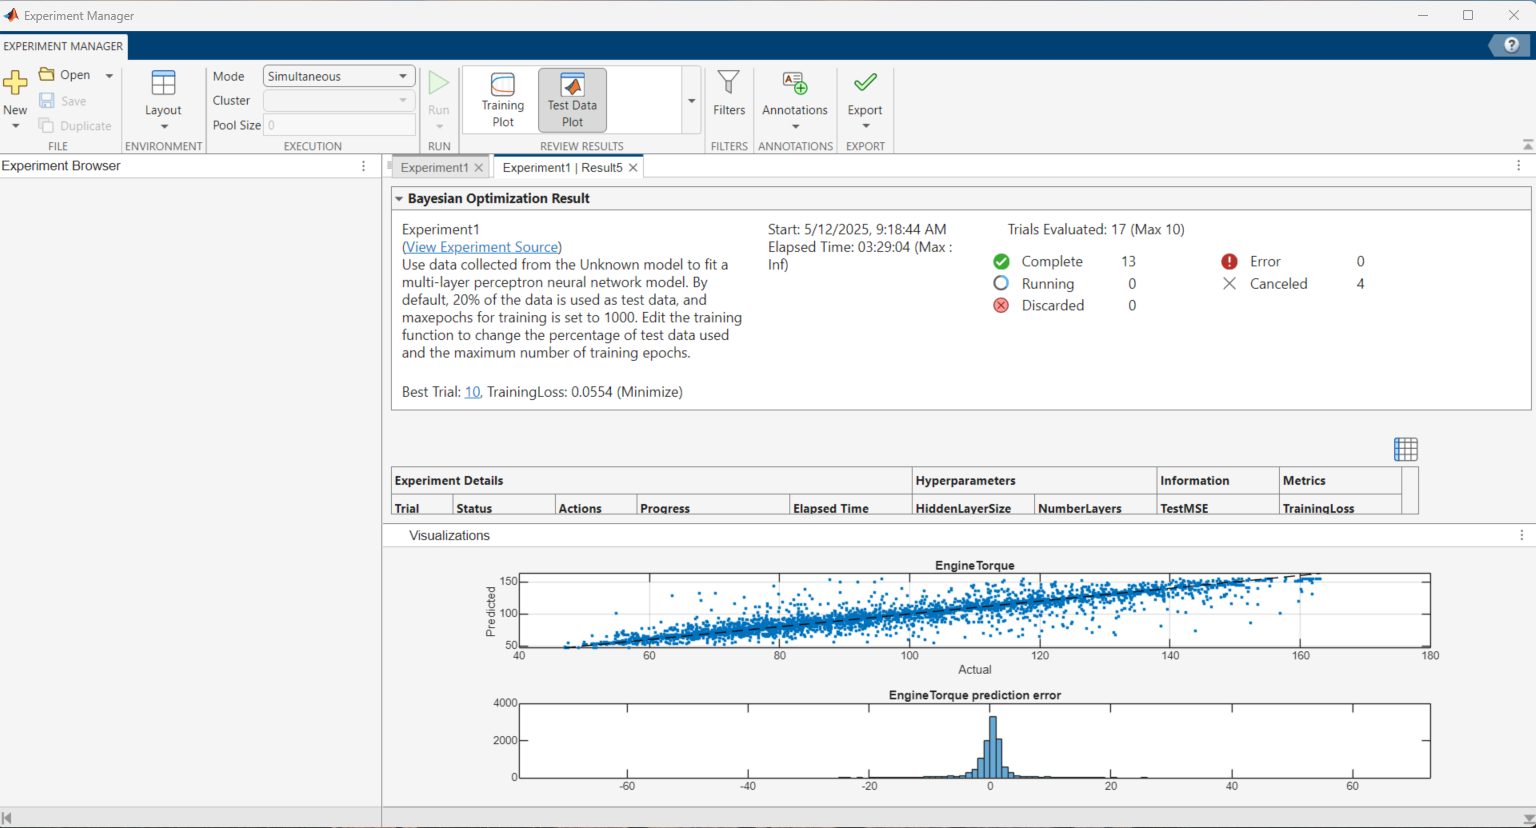 

Extract MLP and Noramlization object that contains both input and output 

else
    load trainingOutputMLP.mat;
end



mlp_rom=trainingOutputMLP.Network;
%Analyzenet so we can see number of learnables
analyzeNetwork(mlp_rom);



Create a Table of Normalization Values

NormalizationValues=trainingOutputMLP.Normalization;

p=NormalizationValues.Sigma;
p1=NormalizationValues.Mu;
temp=table(p',p1');
NormTable=temp;
NormTable.Properties.RowNames=[Inputs,Output];
NormTable.Properties.VariableNames=["Sigma","Mu"];


Now Start integrating Model in Simulink, Point to the network and add Normalization and Denormalization blocks using the Network from above and Data from above.

simulink

- Open   MLP_ROM.slx in the Model folder

- Link Playback to IOData and View Data trough Block parameter

- Open MLP Model Subsystem, and ROM then attach predict model to MLPNetwork.mat and examine the Normalizer and Denormalize blocks

- Run the Model and verify the data in Data Inspector, 

- Go to Apps and open SIL/PIL manager and select the Model Blocks in SIL/PIL Model and Verify